# **Dabrowska Data Tutorial**

## Load the NDI session containing the datasets

% Update for cloud
dataParentDir = fullfile(userpath,'data');
dataPath = fullfile(dataParentDir,'Dabrowska');
session = ndi.session.dir(dataPath);

mksqlite Version 2.13 (ID: 2.13), an interface from MATLAB(R) to SQLite
(c) 2008-2022 by Martin Kortmann <mail@kortmann.de>
                 Andreas Martin  <andimartin@users.sourceforge.net>
based on SQLite Version 3.39.2 - http://www.sqlite.org
mksqlite utilizes:
 - DEELX perl compatible regex engine Version 1.3 (Sswater@gmail.com)
 - BLOSC/LZ4 1.21.6.dev compression algorithm (Francesc Alted / Yann Collett) 
 - MD5 Message-Digest Algorithm (RFC 1321) implementation by Alexander Peslyak
 - RFC-4122 UUID extension (sqlite.org)
   
Platform: MACA64, little endian



## View subjects

Each individual animal is referred to as a **subject** and has a unique local identifier. The local identifier for these experiments contains information about each subjects':

- **strain** (e.g. `sd` for Sprague-Dawley)

- **species** (e.g. `rat` for Rattus norvegicus)

- **genotype** (e.g. `wt` for wild-type)

- **experiment date **(e.g. `210406` for June 4, 2021)

- (optional) **additional identifier** (e.g. `175` for animal #175 in the EPM/FPS dataset)

Each local identifier maps to an alphanumeric document identifier in the database.

### Retrieve subject documents and ids

% Get all subject documents
query = ndi.query('','isa','subject');
subjectDocsAll = session.database_search(query);

% Get all subject ids (local and global)
subjectLocalID = cellfun(@(s) s.document_properties.subject.local_identifier,subjectDocsAll,'UniformOutput',false)';
subjectDocumentID = cellfun(@(s) s.document_properties.base.id,subjectDocsAll,'UniformOutput',false)';
tableSubjectID = table(subjectLocalID,subjectDocumentID)

tableSubjectID = 180×2 table
                           subjectLocalID                                      subjectDocumentID          
    _____________________________________________________________    _____________________________________

    {'sdwi_rat_CRFCre_210818@dabrowska-lab.rosalindfranklin.edu'}    {'41269386be5c1a63_c0dc09575c7ba7c1'}
    {'sdwi_rat_CRFCre_210618@dabrowska-lab.rosalindfranklin.edu'}    {'41269386be5c69e8_c0c0f0d70fe0301b'}
    {'sdwi_rat_CRFCre_210621@dabrowska-lab.rosalindfranklin.edu'}    {'41269386be5c8e9b_40a05c06e56ea9ba'}
    {'sdwi_rat_CRFCre_210622@dabrowska-lab.rosalindfranklin.edu'}    {'41269386be5cb3a3_c0dd57560e61cc54'}
    {'sdwi_rat_CRFCre_120623@dabrowska-lab.rosalindfranklin.edu'}    {'41269386be5cd609_40d66b1205b62142'}
    {'sdwi_rat_OTRCre_220214@dabrowska-lab.rosalindfranklin.edu'}    {'41269386be5cf3c9_c0d0360100d20610'}
    {'sdwi_rat_OTRCre_220216@dabrowska-lab.ros

### Retrieve documents associated with a given subject

The subjects in these experiments have each been linked with two types of files:

- `openminds_subject`

- `element`

% Identify a subject
subjectName = subjectLocalID(95);
subjectIndex = strcmpi(subjectLocalID,subjectName);

% Get all documents associated with that subject
querySubjectID = ndi.query('','depends_on','subject_id',subjectDocumentID(subjectIndex));
subjectDocs = session.database_search(querySubjectID);
subjectDocsClasses = cellfun(@(d) d.document_properties.document_class.class_name,...
    subjectDocs,'UniformOutput',false)'

subjectDocsClasses = 8×1 cell array
    {'openminds_subject'}
    {'openminds_subject'}
    {'openminds_subject'}
    {'openminds_subject'}
    {'openminds_subject'}
    {'element'          }
    {'element'          }
    {'element'          }


#### Retrieve openMinds documents

OpenMINDs is a framework for associating metadata with a subject. In this dataset, there are 4 types of `openminds_subject` documents:

- Species

- Strain

- GeneticStrainType

- BiologicalSex

Each document provides the names, corresponding ontological ids, and other metadata to fully describe the subject's in these experiments.

% Get only the openMINDS metadata documents for this subject
queryDocType = ndi.query('','isa','openminds');
subjectDocsOpenMINDS = session.database_search(querySubjectID & queryDocType);
subjectDocsOpenMINDSTypes = cellfun(@(d) d.document_properties.openminds.openminds_type,...
    subjectDocsOpenMINDS,'UniformOutput',false)'

subjectDocsOpenMINDSTypes = 5×1 cell array
    {'https://openminds.om-i.org/types/Species'          }
    {'https://openminds.om-i.org/types/Strain'           }
    {'https://openminds.om-i.org/types/GeneticStrainType'}
    {'https://openminds.om-i.org/types/Species'          }
    {'https://openminds.om-i.org/types/BiologicalSex'    }


#### Retrieve element documents

In the NDI framework, a **probe** as an instrument that makes a measurement of or produces a stimulus for a **subject**. Probes are part of a broader class of experiment items that we term **elements.** In these experiments, there are 3 probe types:

- `stimulator`

- `patch-Vm`

- `patch-I`

Each subject is linked to a unique set of probes. The **stimulator** probe is connected to any information about stimuli that the subject received such as electrophysiological bath conditions or experimental approaches (e.g. optogenetic tetanus). The **patch-Vm** and **patch-I** are probes of type **mfdaq** (multifunction data acquisition system) which means that they contain data linked to an acquisition system that stored measurements (i.e. voltage and current) for a set of experimental **epochs**.

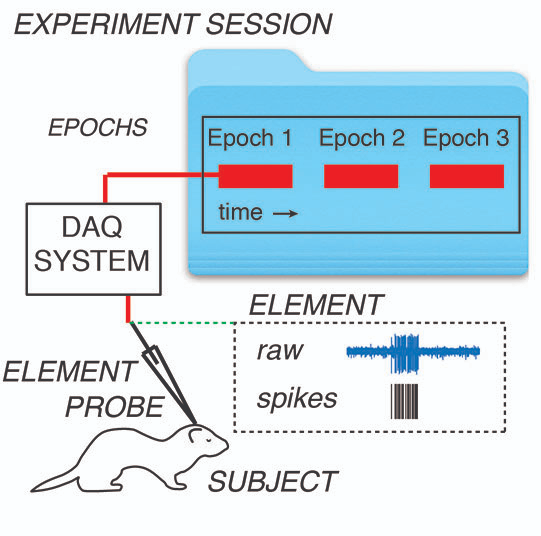

% Get only the element documents for this subject
queryDocType = ndi.query('','isa','element');
subjectDocsElements = session.database_search(querySubjectID & queryDocType);
subjectDocsElementsNames = cellfun(@(d) d.document_properties.element.name,...
    subjectDocsElements,'UniformOutput',false)'

subjectDocsElementsNames = 3×1 cell array
    {'bath_240409_a'}
    {'Vm_240409_a'  }
    {'I_240409_a'   }


### View summary of available openMINDs metadata and elements for all subjects

% View summary table of all subject metadata
subjectSummary = ndi.fun.subjectDocTable(session)

subjectSummary = 180×14 table
                 documentID                                             localID                                    SpeciesName           SpeciesOntology             StrainName                      StrainOntology                GeneticStrainTypeName    GeneticStrainTypeOntology    BiologicalSexName    BiologicalSexOntology                    stimulatorName                     stimulatorType                                      mfdaqName                                            mfdaqType      
    _____________________________________    _____________________________________________________________    _____________________    ___________________    

## View electrophysiology datasets

Each **subject** is associated with a set of **probes** as described above. We can retrieve all probes in the experiment, or we can retrieve only the probes of a particular type or those associated with a particular subject.

*Note: Only the electrophysiology experiments have probes. Behavioral experiments have table row documents (described below).*

% Get all probes
probesAll = session.getprobes();

% Get probes by type (stimulator, patch-Vm, patch-I)
probesBath = session.getprobes('type','stimulator');
probesPatchVm = session.getprobes('type','patch-Vm');
probesPatchI = session.getprobes('type','patch-I');

% Get probes by subject
subjectName = subjectLocalID(27);
subjectIndex = strcmpi(subjectLocalID,subjectName);
probesSubject = session.getprobes('subject_id',subjectDocumentID{subjectIndex})

probesSubject = 3×1 cell array
    {1×1 ndi.probe.timeseries.stimulator}
    {1×1 ndi.probe.timeseries.mfdaq     }
    {1×1 ndi.probe.timeseries.mfdaq     }


### View all epochs for a given subject

Each **subject** is associated with a set of experimental **epochs.** One **epoch** corresponds to one of the original `.mat` files. Each probe is associated with all of a subject's epochs. Let's look at a **stimulator** and **patch-Vm** probe for a given subject.

% Choose a subject
subjectName = subjectLocalID(110);
subjectIndex = strcmpi(subjectLocalID,subjectName);

% Get stimulator probe
probeSubjectStimulator = session.getprobes('subject_id',subjectDocumentID{subjectIndex},...
    'type','stimulator');
probeSubjectStimulator = probeSubjectStimulator{1} % one stimulator probe per subject

probeSubjectStimulator =   stimulator with properties:

               session: [1×1 ndi.session.dir]
                  name: 'bath_250203_a'
                  type: 'stimulator'
             reference: 1
    underlying_element: []
                direct: 1
            subject_id: '41269386be633fd5_40917eaaade10ed9'
          dependencies: [0×1 struct]
            identifier: '41269386bf1aa03b_40d153ada4c5036b'


% Get patch-Vm probe
probesSubjectPatchVm = session.getprobes('subject_id',subjectDocumentID{subjectIndex},...
    'type','patch-Vm');
probeSubjectPatchVm = probesSubjectPatchVm{1} % one patch-Vm probe per subject

probeSubjectPatchVm =   mfdaq with properties:

               session: [1×1 ndi.session.dir]
                  name: 'Vm_250203_a'
                  type: 'patch-Vm'
             reference: 1
    underlying_element: []
                direct: 1
            subject_id: '41269386be633fd5_40917eaaade10ed9'
          dependencies: [0×1 struct]
            identifier: '41269386bf1aaf2d_c0d395d66b539ad8'


Now, let's look at their associated **epochs**. These will be identical for all **probes** of a given **subject**.

% Get epochs associated with the stimulator probe
epochTableStimulator = probeSubjectStimulator.epochtable

epochTableStimulator = 1×22 struct array with fields:
    epoch_number
    epoch_id
    epoch_session_id
    epochprobemap
    epoch_clock
    t0_t1
    underlying_epochs


% Get epochs associated with the patch-Vm probe
epochTablePatchVm = probeSubjectPatchVm.epochtable

epochTablePatchVm = 1×22 struct array with fields:
    epoch_number
    epoch_id
    epoch_session_id
    epochprobemap
    epoch_clock
    t0_t1
    underlying_epochs


### Retrieve stimulus documents

Let's look at the documents associated with a given **stimulator**. For all electrophysiology epochs in these experiemnts, there will be a `stimulus_bath` document describing all compounds in the bath. For optogenetic epochs there will also be a `stimulus_approach` document describing if the epoch was before or after optogenetic tetanus. Both the `stimulus_bath` and `stimulus_approach` documents are unique for each **epoch** and are associated with the subject's **stimulator** probe. For the purpose's of this tutorial, we will look at a subject which received optogenetic stimulation and therefore has both stimulus document types.

% Choose a subject
subjectName = 'sdwi_rat_AVPCre_230404@dabrowska-lab.rosalindfranklin.edu';
subjectIndex = strcmpi(subjectLocalID,subjectName);

% Get the stimulator
probeSubjectStimulator = session.getprobes('subject_id',subjectDocumentID{subjectIndex},...
    'type','stimulator');
probeSubjectStimulator = probeSubjectStimulator{1}; % one stimulator probe per subject

% Retrieve all documents associated with the stimulator
stimulatorID = probeSubjectStimulator.identifier;
queryStimulatorID = ndi.query('','depends_on','stimulus_element_id',stimulatorID);
stimulatorDocs = session.database_search(queryStimulatorID);

#### Retrieve all stimulus documents associated with a given epoch

Now, let's look at the documents associated with only one of the **subject**'s **epochs**.

% Get the epochtable associated with the stimulator
epochTableStimulator = probeSubjectStimulator.epochtable;

% Select an epoch_number
epochNums = [epochTableStimulator.epoch_number];
epochNum = epochNums(1);

% Retrieve all documents associated with that epoch
epochID = epochTableStimulator(epochNum).epoch_id;
queryEpochID = ndi.query('epochid.epochid','exact_string',epochID);
epochDocs = session.database_search(queryEpochID);

#### View stimulus bath documents for a given epoch

For all electrophysiology/optogenetic experiments, there will be one `stimulus_bath` document per **epoch**.

% Retrieve only the stimulus_bath document
stimulusBathDoc = ndi.database.fun.finddocs_elementEpochType(session,...
    stimulatorID,epochID,'stimulus_bath');

% Get metadata contained in the stimulus_bath document
stimulusBath = stimulusBathDoc{1}.document_properties.stimulus_bath;

% Get stimulus_bath location info
location = struct2table(stimulusBath.location)

location = 1×2 table
    ontologyNode               name          
    _____________    ________________________

    NCIm:C0179246    Baths, Water, Laboratory


% Get stimulus_bath mixture info (and convert to table)
mixture = stimulusBath.mixture_table;
mixture = ndi.database.fun.readtablechar(mixture,'.txt','Delimiter',',')

mixture = 11×5 table
       ontologyName                                                 name                                               value          ontologyUnit            unitName   
    __________________    _________________________________________________________________________________________    ______    ______________________    ______________

    {'NCIm:C0037494' }    {'sodium chloride'                                                                      }    0.1225    {'OM:MolarVolumeUnit'}    {'Molar'     }
    {'NCIm:C0032825' }    {'potassium chloride'                                                                   }    0.0035    {'OM:MolarVolumeUnit'}    {'Molar'     }
    {'NCIm:C0074722' }    {'sodium bicarbonate'                                                                   }     0.025   

#### View stimulus approach documents for a given epoch

For the optogenetic experiments, there will be one `stimulus_approach` document per **epoch**.

% Retrieve only the stimulus_approach document
stimulusApproachDoc = ndi.database.fun.finddocs_elementEpochType(session,...
    stimulatorID,epochID,'openminds_stimulus');

% Get metadata contained in the stimulus_approach document
stimulusApproach = stimulusApproachDoc{1}.document_properties.openminds.fields;

% Display the stimulus approach id, name, description
stimulusApproach = cell2table({stimulusApproach.preferredOntologyIdentifier,...
    stimulusApproach.name,stimulusApproach.description}',...
    'RowNames',{'id','name','description'},...
    'VariableNames',{'value'})

stimulusApproach = 3×1 table
                                                    value                                  
                   ________________________________________________________________________

    id             {'NDIC:00000025'                                                       }
    name           {'Approach: Before optogenetic tetanus'                                }
    description    {'The measurement is performed before an optogenetic tetanus stimulus.'}


### Retrieve mfdaq timeseries data

As described above, the **mfdaq** probes are associated with the same **epochs** as the **stimulator** but are associated with **timeseries** data. Let's take a look at the data associated with the same **subject** and **epoch** as the one we just viewed.

% Get the patch-Vm probe
probesSubjectPatchVm = session.getprobes('subject_id',subjectDocumentID{subjectIndex},...
    'type','patch-Vm');
probeSubjectPatchVm = probesSubjectPatchVm{1};

% Get the patch-I probe
probesSubjectPatchI = session.getprobes('subject_id',subjectDocumentID{subjectIndex},...
    'type','patch-I');
probeSubjectPatchI = probesSubjectPatchI{1};

% Read the patch-Vm timeseries
[dataVm,timeVm] = probeSubjectPatchVm.readtimeseries(epochNum,-inf,inf);

% Read the patch-I timeseries
[dataI,timeI] = probeSubjectPatchI.readtimeseries(epochNum,-inf,inf);

### Plot electrophysiology trace

All traces for one epoch are in a continuous timeseries with gaps of time (corresponding to the exact trigger time) in between each of the current steps.

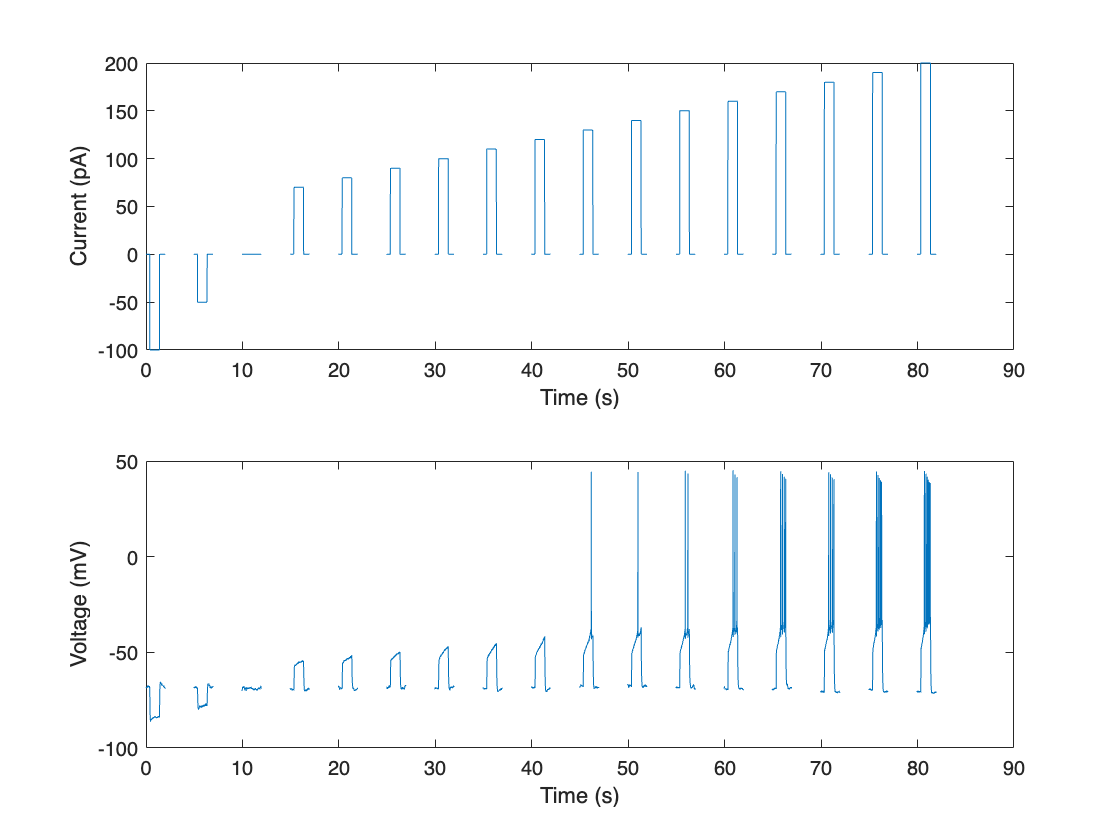

figure;
subplot(211); plot(timeI,dataI); xlabel('Time (s)'); ylabel('Current (pA)')
subplot(212); plot(timeVm,dataVm); xlabel('Time (s)'); ylabel('Voltage (mV)')

We can remove the gaps to retrieve the original matrix of data (rows = time, columns = current steps).

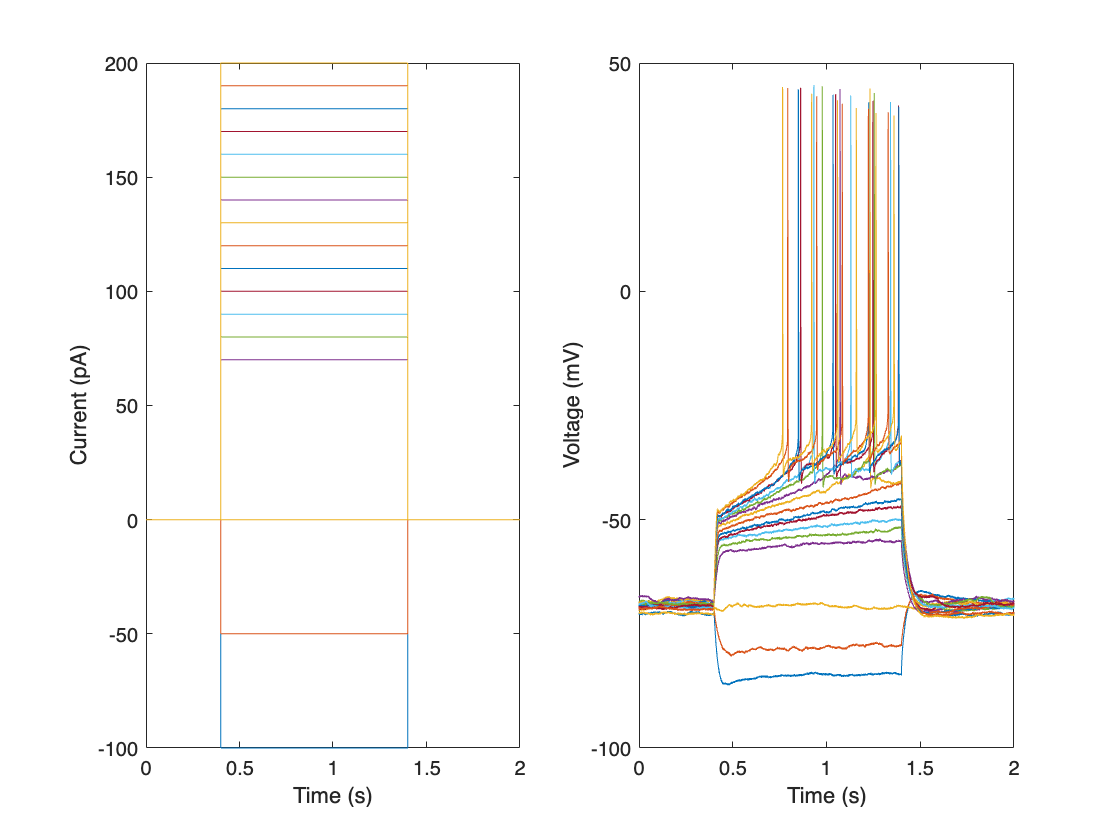

% Find indices where traces start and end
traceStarts = find(diff([1;isnan(dataI)]) == -1);
traceEnds = find(diff([isnan(dataI);0]) == 1);

% Get number of current steps and number of timepoints per step
numSteps = numel(traceStarts);
numTimepoints = max(traceEnds - traceStarts) + 1;

% Reformat data into a matrix (time x steps)
timeMatrix = timeI(1:numTimepoints);
dataVmMatrix = nan(numTimepoints,numSteps);
dataIMatrix = nan(numTimepoints,numSteps);
for i = 1:numSteps
    dataVmMatrix(:,i) = dataVm(traceStarts(i):traceEnds(i));
    dataIMatrix(:,i) = dataI(traceStarts(i):traceEnds(i));
end

% Plot reformatted traces
figure;
subplot(121); plot(timeMatrix,dataIMatrix); xlabel('Time (s)'); ylabel('Current (pA)')
subplot(122); plot(timeMatrix,dataVmMatrix); xlabel('Time (s)'); ylabel('Voltage (mV)')

## View behavioral datasets

Each row of the original data tables for "Elevated Plus Maze (EPM)" and "Fear-Potentiated Startle (FPS)" experiments corresponded to a single subject or trial. We have therefore saved each row of the EPM and FPS data tables as an `ontologyTableRow` document in NDI-cloud database. The following tutorial will guide you through browsing the data in the database, reconstructing the original data tables, and re-analyzing/plotting the data.

### Retrieve behavior dataset documents and convert to tables

% Get all ontologyTableRow documents
query = ndi.query('','isa','ontologyTableRow');
docsAll = session.database_search(query);

% Get Elevated Plus Maze documents/table
query = ndi.query('ontologyTableRow.names','contains_string','Elevated Plus Maze');
docsEPM = session.database_search(query);
tableEPM = ndi.fun.doc.ontologyTableRowDoc2Table(docsEPM)

tableEPM = 45×51 table
    elevatedPlusMazeTestIdentifier    treatmentCNOSalineAdministration    elevatedPlusMazeOpenArmNorthEntries    elevatedPlusMazeOpenArmSouthEntries    elevatedPlusMazeOpenArmTotalEntries    elevatedPlusMazeOpenArmNorthHeadEntries    elevatedPlusMazeOpenArmSouthHeadEntries    elevatedPlusMazeOpenArmTotalHeadEntries    elevatedPlusMazeOpenArmNorthTime    elevatedPlusMazeOpenArmSouthTime    elevatedPlusMazeOpenArmTotalTime    elevatedPlusMazeOpenArmTotalPercentTimeDuringTestDuration    elevatedPlusMazeOpenArmNorthLatencyToFirstEntry    elevatedPlusMazeOpenArmSouthLatencyToFirstEntry    elevatedPlusMazeOpenArmTotalLatencyToFirstEntry    elevatedPlusMazeOpenArmNorthTimeMovingTowards    elevat

% Get Fear-Potentiated documents/table
query = ndi.query('ontologyTableRow.names','contains_string','Fear-Potentiated Startle');
docsFPS = session.database_search(query);
tableFPS = ndi.fun.doc.ontologyTableRowDoc2Table(docsFPS)

tableFPS = 6160×13 table
    fpsTrialNumber    fpsTrialTypeIdentifier     fpsApparatusChamberIdentifier    experimentalGroupCode    asrNumberOfSamplesInWindow    asrSamplingRate    asrStartleWindowOnsetAttribute    asrMaximumAmplitude    asrTimeToMaximumAmplitude    asrAverageAmplitudeInWindow    experimentTrialExecutionTimestamp    fpsExperimentalPhaseTestName                         subjectLocalIdentifier                      
    ______________    _______________________    _____________________________    _____________________    __________________________    _______________    ______________________________    ___________________ 

### Browse behavior dataset variables

% Get list of all variables
[fullNames,shortNames,ontologyNodes] = ...
    ndi.fun.doc.ontologyTableRowVars(session);

% Look up a variable in the ontology
termName = shortNames(27);
termIndex = strcmpi(shortNames,termName);
termID = ontologyNodes{termIndex};
[id,name,prefix,definition,synonyms,shortName] = ...
    ndi.ontology.lookup(termID);

Loading NDI ontology list from JSON...
NDI ontology list loaded successfully.
Parsing OBO file: /Users/jhaley/Documents/MATLAB/tools/NDI-matlab/ndi_common/controlled_vocabulary/empty.obo...
OBO file parsed and cached successfully. Found 99 terms.



% Display the variable's id, name, definition, and short name
termInfo = cell2table({id,name,definition,shortName}',...
    'RowNames',{'id','name','definition','shortName'},...
    'VariableNames',{'value'})

termInfo = 4×1 table
                                                                                                                                  value                                                                                                                 
                  ______________________________________________________________________________________________________________________________________________________________________________________________________________________________________

    id            {'EMPTY:00000128'                                                                                                                                                                                                                    }
    name          {'Elevated Plus Maze: closed arm total - percent time during test duration'                                                                      

### Plot example EPM figure

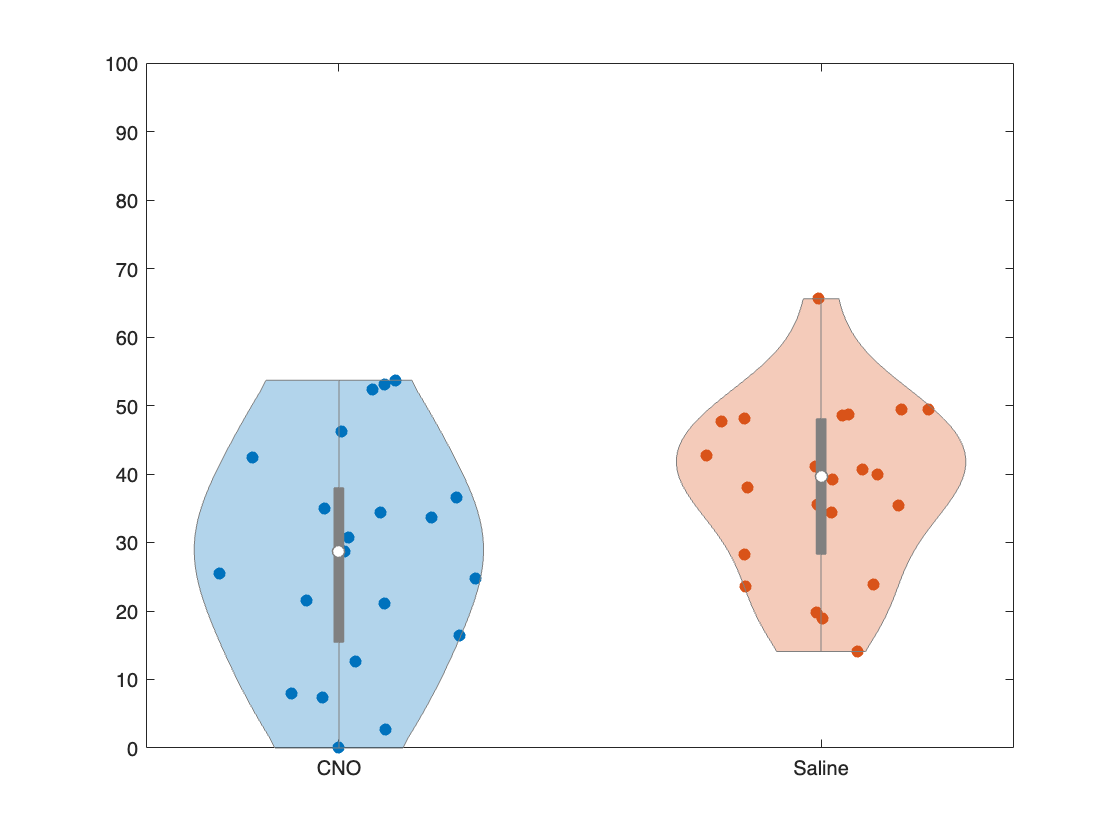

% Define grouping and plotting variables
groupingVariable = 'treatmentCNOSalineAdministration';
plottingVariable = 'elevatedPlusMazeOpenArmTotalPercentTimeDuringTestDuration';
% make dropdown

% Get valid row indices
validRows = ~tableEPM.dataExclusionFlag & ... % missing mCherry expression
    ~isnan(tableEPM.(plottingVariable)); % missing data points

% Plot % time in open arms (Figure 4G)
figure; violinplot(tableEPM{validRows,plottingVariable},...
    categorical(tableEPM{validRows,groupingVariable}));
ylim([0 100])

### Plot example FPS figure

% Get average startle amplitude for each context, subject, and trial
tableStartleAmplitude = groupsummary(tableFPS,...
    {'fpsExperimentalPhaseTestName','subjectLocalIdentifier','fpsTrialTypeIdentifier'},...
    'mean','asrMaximumAmplitude')

tableStartleAmplitude = 392×5 table
    fpsExperimentalPhaseTestName                         subjectLocalIdentifier                          fpsTrialTypeIdentifier     GroupCount    mean_asrMaximumAmplitude
    ____________________________    _________________________________________________________________    _______________________    __________    ________________________

           {'Context 1'}            {'sdwi_rat_OTRCre_220819_175@dabrowska-lab.rosalindfranklin.edu'}    {'Startle 95 dB Trial'}        30                 33.667         
           {'Context 1'}            {'sdwi_rat_OTRCre_220819_180@dabrowska-lab.rosalindfranklin.edu'}    {'Startle 95 dB Trial'}        30                 53.367         
           {'Context 1'}            {'sdwi_rat_OTRCre_220819_181@dabrowska-lab.rosalindfranklin.edu'}    {'St

% Get row indices corresponding to the first cue test
cueTestRows = strcmpi(tableStartleAmplitude.fpsExperimentalPhaseTestName,'Cue test 1');

% Get row indices corresponding to L+N and N conditions
lightNoiseRows = strcmpi(tableStartleAmplitude.fpsTrialTypeIdentifier,'FPS (L+N) Testing Trial');
noiseOnlyRows = strcmpi(tableStartleAmplitude.fpsTrialTypeIdentifier,'FPS (N) Testing Trial');

% Calculate cued fear for first cue test
tableLightNoise = tableStartleAmplitude(cueTestRows & lightNoiseRows,:);
tableNoiseOnly = tableStartleAmplitude(cueTestRows & noiseOnlyRows,:);
tableCuedFear = join(tableLightNoise,tableNoiseOnly,...
    'Keys',{'fpsExperimentalPhaseTestName','subjectLocalIdentifier'},...
    'LeftVariables',{'fpsExperimentalPhaseTestName','subjectLocalIdentifier','mean_asrMaximumAmplitude'},...
    'RightVariables','mean_asrMaximumAmplitude');
tableCuedFear.cuedFear = 100*(tableCuedFear.mean_asrMaximumAmplitude_tableLightNoise - ...
    tableCuedFear.mean_asrMaximumAmplitude_tableNoiseOnly)./...
    tableCuedFear.mean_asrMaximumAmplitude_tableNoiseOnly; % 100*(LN - N)/N

% Define grouping and plotting variables
groupingVariable = 'treatmentCNOSalineAdministration';
plottingVariable = 'cuedFear';

% Add grouping variable info from EPM table
tableCuedFear = join(tableCuedFear,tableEPM(:,{'subjectLocalIdentifier',groupingVariable}))

tableCuedFear = 28×6 table
    fpsExperimentalPhaseTestName                         subjectLocalIdentifier                          mean_asrMaximumAmplitude_tableLightNoise    mean_asrMaximumAmplitude_tableNoiseOnly    cuedFear    treatmentCNOSalineAdministration
    ____________________________    _________________________________________________________________    ________________________________________    _______________________________________    ________    ________________________________

           {'Cue test 1'}           {'sdwi_rat_OTRCre_220819_175@dabrowska-lab.rosalindfranklin.edu'}                      38.7                                        28.4                      36.268                {'Saline'}           
           {'Cue test 1'}           {'sdwi_rat_OTRCre_220

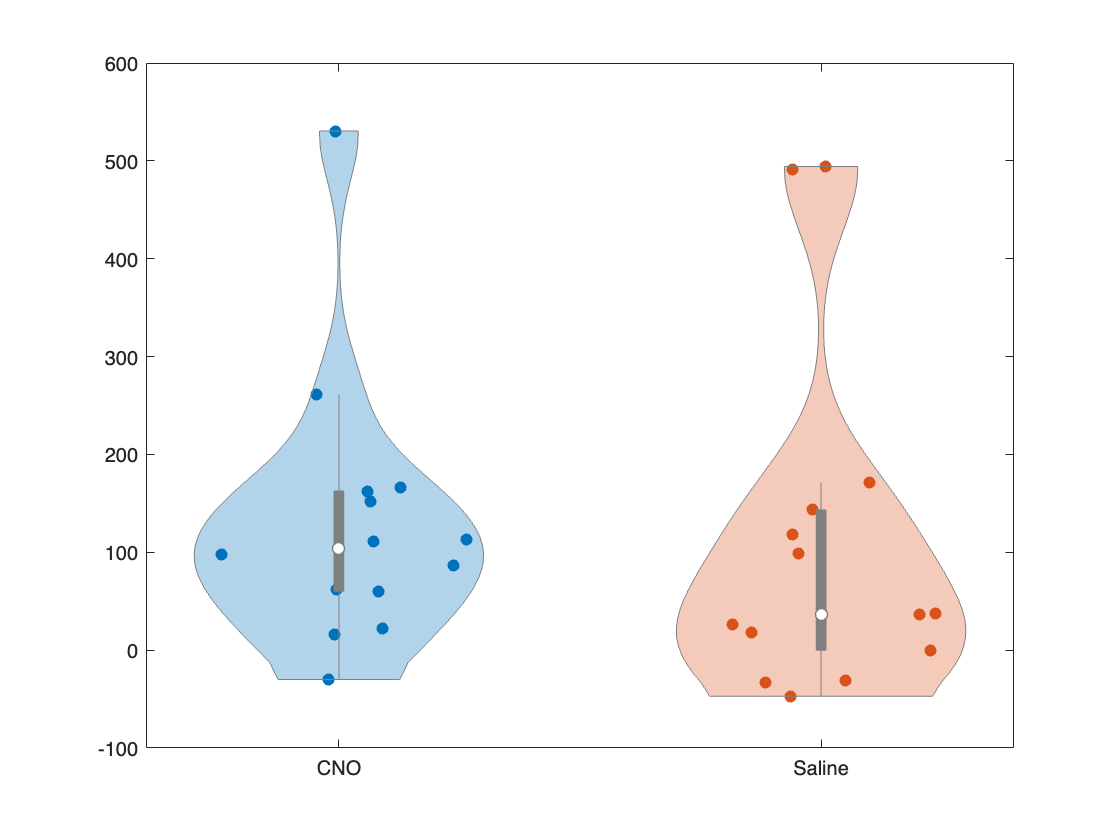

% Plot cued fear % in first recall (Figure 4D')
figure; violinplot(tableCuedFear{:,plottingVariable},...
    categorical(tableCuedFear{:,groupingVariable}));